## **Kobylański Przemysław, 297253**

## **Metodu numeryczne - projekt 1**

2.1. Dokonać interpolacji liniowej i interpolacji splajnami trzeciego stopnia funkcji y=x^`2*`sin(πx) w przedziale [−1; 4] z krokiem 0.5. Narysować wykres danej funkcji i funkcji przybliżającej w jednym układzie współrzędnych natomiast wykres błędu interpolacji w drugim. Węzły interpolacji zaznaczyć 'o'. Wyznaczyć maksymalną wartość bezwzględnego błędu interpolacji w rozpatrywanym przedziale. Porównać metody interpolacji.

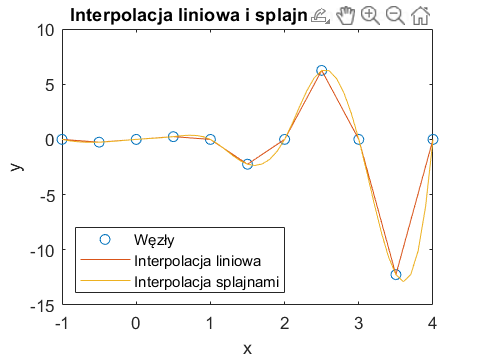

clear all

%węzły interpolacji
x=-1:0.5:4;
y=x.^2.*sin(pi().*x);

%zagęszczony wektor żeby lepiej interpolować
xi = -1 : 0.1 :4;
yi = xi.^2.*sin(pi().*xi);

%interpolacja liniowa
intLiniowa=interp1(x,y,xi);
%interpolacja splajnami 3 stopnia
intSplajn=spline(x,y,xi);

%porównanie na wykresach
figure;
plot(x, y, 'o', xi, intLiniowa, xi, intSplajn);
title('Interpolacja liniowa i splajnami 3 stopnia');
xlabel('x');
ylabel('y');
legend('Węzły', 'Interpolacja liniowa', 'Interpolacja splajnami','Location', 'southwest');

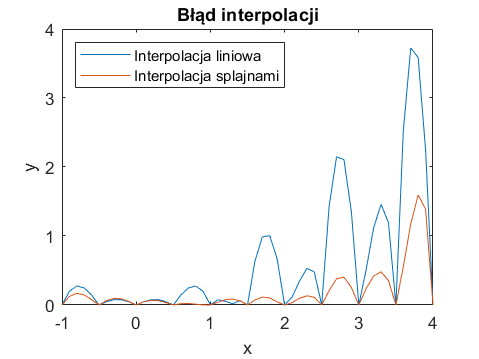

%węzły interpolacji

%maks błąd bezwzględny
errorLiniowa=abs(intLiniowa-yi);
maxErrorLiniowa=max(errorLiniowa);
errorSplajn=abs(intSplajn-yi);
maxErrorSplajn=max(errorSplajn);
%wykres z błędami
figure;
plot(xi, errorLiniowa, xi, errorSplajn);
legend('Interpolacja liniowa', 'Interpolacja splajnami');
title('Błąd interpolacji');
xlabel('x');
ylabel('y');
legend('Interpolacja liniowa', 'Interpolacja splajnami','Location', 'northwest');


disp("Maksymalny błąd bezwzględny interpolacji liniowej wynosi:" + maxErrorLiniowa);

Maksymalny błąd bzewzględny interpolacji liniowej wynosi:3.7254


disp("Maksymalny błąd bezwzględny interpolacji splajnami wynosi:" + maxErrorSplajn);

Maksymalny błąd bzewzględny interpolacji liniowej wynosi:1.5936


Interpolacja splajnami 3 stopnia daje znacząco lepsze rezultaty

2.2. Napisać skrypt Matlaba realizujący interpolację Lagrange'a i Newtona (MojaInterpLagrange.m i MojaInterpNewton.m), a następnie korzystając z obydwu metod zbudować wielomian interpolacyjny 4-go stopnia dla następujących danych:

i xi yi = f (xi)

0 0.0 -6.00000

1 0.1 -5.89483

2 0.3 -5.65014

3 0.6 -5.17788

4 1.0 -4.28172

Następnie do tablicy dodać nowy punkt f (1.1) = −3.99583 i zbudować wielomian interpolacyjny 5-go stopnia. Porównać efektywność działania procedur dla dwóch wielomianów interpolacyjnych poprzez pomiar czasu. Wyznaczyć wartość f (0.2). Narysować odpowiednie wykresy. 

clear all;
syms x;
%Interpolacja metodą Lagrange'a
xi = [0.0, 0.1, 0.3, 0.6, 1.0];
fxi = [-6.00000, -5.89483, -5.65014, -5.17788, -4.28172];
tic;
Lagrange = MojaInterpLagrange(xi, fxi);
czas=toc;
disp("Metoda Lagrange'a");

Metoda Lagrange'a


disp("Wielomian interpolacyjny 4-st:");

Wielomian interpolacyjny 4-st:


disp(Lagrange);

$$\frac{276541189493879375\,x\,\left(x-1\right)\,\left(x-\frac{3}{5}\right)\,\left(x-\frac{3}{10}\right)}{422212465065984}-\frac{496991570284983125\,x\,\left(x-1\right)\,\left(x-\frac{3}{5}\right)\,\left(x-\frac{1}{10}\right)}{1108307720798208}-\frac{100\,\left(10\,x-1\right)\,\left(x-1\right)\,\left(x-\frac{3}{5}\right)\,\left(x-\frac{3}{10}\right)}{3}+\frac{364360913102642875\,x\,\left(x-1\right)\,\left(x-\frac{1}{10}\right)\,\left(x-\frac{3}{10}\right)}{2533274790395904}-\frac{75324814830096875\,x\,\left(x-\frac{3}{5}\right)\,\left(x-\frac{1}{10}\right)\,\left(x-\frac{3}{10}\right)}{4433230883192832}$$

disp("Czas:");

Czas:


disp(czas);

    0.0929




% Lagrange - 5 stopień
xi5 = [0.0, 0.1, 0.3, 0.6, 1.0, 1.1];
fxi5 = [-6.00000, -5.89483, -5.65014, -5.17788, -4.28172, -3.99583];
tic;
Lagrange5 = MojaInterpLagrange(xi5, fxi5);
czas=toc;
disp("Wielomian interpolacyjny 5-st:");

Wielomian interpolacyjny 5-st:


disp(Lagrange5);

$$\frac{2484957851424915625\,x\,\left(x-1\right)\,\left(x-\frac{3}{5}\right)\,\left(x-\frac{1}{10}\right)\,\left(x-\frac{11}{10}\right)}{4433230883192832}-\frac{1124726156189740625\,x\,\left(x-1\right)\,\left(x-\frac{3}{5}\right)\,\left(x-\frac{1}{10}\right)\,\left(x-\frac{3}{10}\right)}{12384898975268864}-\frac{276541189493879375\,x\,\left(x-1\right)\,\left(x-\frac{3}{5}\right)\,\left(x-\frac{3}{10}\right)\,\left(x-\frac{11}{10}\right)}{422212465065984}-\frac{364360913102642875\,x\,\left(x-1\right)\,\left(x-\frac{1}{10}\right)\,\left(x-\frac{3}{10}\right)\,\left(x-\frac{11}{10}\right)}{1266637395197952}+\frac{376624074150484375\,x\,\left(x-\frac{3}{5}\right)\,\left(x-\frac{1}{10}\right)\,\left(x-\frac{3}{10}\right)\,\left(x-\frac{11}{10}\right)}{2216615441596416}+\frac{1000\,\left(10\,x-1\right)\,\left(x-1\right)\,\left(x-\frac{3}{5}\right)\,\left(x-\frac{3}{10}\right)\,\left(x-\frac{11}{10}\right)}{33}$$

disp("Czas:");

Czas:


disp(czas);

    0.0581




% Obliczenie wartości funkcji interpolującej w punkcie (0,2)
x0 = 0.2;
f0 = double(subs(Lagrange5, x0));

% Wyświetlenie wyniku
disp(['Wartość funkcji w punkcie (0.2): ', num2str(f0)]);

Wartość funkcji w punkcie (0.2): -5.7786



%Interpolacja metodą Newtona
xi = [0.0, 0.1, 0.3, 0.6, 1.0];
fxi = [-6.00000, -5.89483, -5.65014, -5.17788, -4.28172];
tic;
Newton = MojaInterpNewtona(xi, fxi);
czas=toc;
disp("Metoda Newtona");

Metoda Newtona


disp("Wielomian interpolacyjny 4-st:");

Wielomian interpolacyjny 4-st:


disp(Newton);

$$x\,\left(\left(\left(\frac{1135193048929907\,x}{18014398509481984}+\frac{3989974812726791}{22517998136852480}\right)\,\left(x-\frac{3}{10}\right)+\frac{5156621573339067}{9007199254740992}\right)\,\left(x-\frac{1}{10}\right)+\frac{10517}{10000}\right)-6$$

disp("Czas:");

Czas:


disp(czas);

    0.0263




% Newton - 5 stopień
xi5 = [0.0, 0.1, 0.3, 0.6, 1.0, 1.1];
fxi5 = [-6.00000, -5.89483, -5.65014, -5.17788, -4.28172, -3.99583];
tic;
Newton5 = MojaInterpLagrange(xi5, fxi5);
czas=toc;
disp("Wielomian interpolacyjny 5-st:");

Wielomian interpolacyjny 5-st:


disp(Newton5);

$$\frac{2484957851424915625\,x\,\left(x-1\right)\,\left(x-\frac{3}{5}\right)\,\left(x-\frac{1}{10}\right)\,\left(x-\frac{11}{10}\right)}{4433230883192832}-\frac{1124726156189740625\,x\,\left(x-1\right)\,\left(x-\frac{3}{5}\right)\,\left(x-\frac{1}{10}\right)\,\left(x-\frac{3}{10}\right)}{12384898975268864}-\frac{276541189493879375\,x\,\left(x-1\right)\,\left(x-\frac{3}{5}\right)\,\left(x-\frac{3}{10}\right)\,\left(x-\frac{11}{10}\right)}{422212465065984}-\frac{364360913102642875\,x\,\left(x-1\right)\,\left(x-\frac{1}{10}\right)\,\left(x-\frac{3}{10}\right)\,\left(x-\frac{11}{10}\right)}{1266637395197952}+\frac{376624074150484375\,x\,\left(x-\frac{3}{5}\right)\,\left(x-\frac{1}{10}\right)\,\left(x-\frac{3}{10}\right)\,\left(x-\frac{11}{10}\right)}{2216615441596416}+\frac{1000\,\left(10\,x-1\right)\,\left(x-1\right)\,\left(x-\frac{3}{5}\right)\,\left(x-\frac{3}{10}\right)\,\left(x-\frac{11}{10}\right)}{33}$$

disp("Czas:");

Czas:


disp(czas);

    0.0532




% Obliczenie wartości funkcji interpolującej w punkcie (0,2)
x0 = 0.2;
f0 = double(subs(Newton5, x0));

% Wyświetlenie wyniku
disp(['Wartość funkcji w punkcie (0.2): ', num2str(f0)]);

Wartość funkcji w punkcie (0.2): -5.7786


2.4. Badania naukowców wykazały, ze pewien rzadki gatunek ptaka Ledwolotus dziwolongus pokonuje corocznie takie same trasy, których kształt można opisać za pomocą wykresu wielomianu. W wyniku chwilowej utraty zasilania w centrum badawczym znaczna część danych dotyczących tego badania została utracona i pozostało jedynie kilka par punktów krzywej: (0, −4), (1, 3), (3, 5), (2, 2). Odtworzyć trasę lotów ledwolotusa, znajdując wielomian moąliwie najniższego stopnia, którego wykres przechodzi przez powyższe pary punktów. Zadanie rozwiązać dowolną metodą

clear all

%Rozwiązanie metodą interpolacji Newtona
xi = [0 1 3 2];
fxi = [-4 3 5 2];
Newton = MojaInterpNewtona(xi, fxi);
disp("Wielomian interpolacyjny Newtona:");

Wielomian interpolacyjny Newtona:


disp(Newton);

$$x\,\left(\left(2\,x-8\right)\,\left(x-1\right)+7\right)-4$$

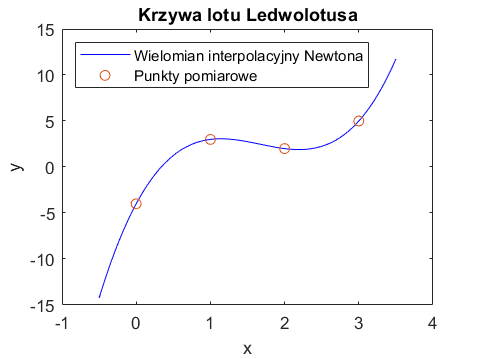


% Przygotowanie danych do wykresu
a = min(xi)-0.5;
b = max(xi)+0.5; 
dx = 0.01; % krok próbkowania
x_vals = a:dx:b;
y_vals = double(subs(Newton, x_vals));

% Rysowanie wykresu
plot(x_vals, y_vals, 'b', xi, fxi, 'o');
xlabel('x');
ylabel('y');
title('Krzywa lotu Ledwolotusa');
legend('Wielomian interpolacyjny Newtona', 'Punkty pomiarowe',Location='northwest');

2.5. Pewnego dnia, w godzinach od 7:50 do 10:20 na Wydziale Mechatroniki odbywał się egzamin z przedmiotu Metody Numeryczne. Ponieważ atmosfera, jak na każdym egzaminie, była gorąca, zdecydowano się zmierzyć temperaturę panującą w sali w trakcie oraz po egzaminie. Pomiary były dokonywane co pełną godzinę: o godzinie 8 było 20 stopni, o 9 - 24 stopnie, o 10 - 26 stopni, a o 11 temperatura spadła z powrotem do 20 stopni Celsjusza. Ponadto, okazało się »e zmiany temperatury w sali można opisać w funkcji czasu T (t), która jest wielomianem trzeciego stopnia. Dokonać interpolacji metodą Lagrange'a i Newtona tej funkcji i odpowiedzie¢ na pytanie: jaka temperatura panowała w sali o godzinie 10:30

clear all

t = [ 8, 9, 10, 11];
T = [ 20, 24, 26, 20];
% Czas o którym chcemy poznać temperaturę
tint = 10.5;
% Metoda Newtona
Newton = MojaInterpNewtona(t, T);
tintNewton = double(subs(Newton, tint));
disp("Temperatura o godzinie 10:30 wg. interpolacji Newtona: " + tintNewton);

Temperatura o godzinie 10:30 wg. interpolacji Newtona: 24.375



% Metoda Lagrange'a
Lagrange = MojaInterpLagrange(t, T);
tintLagrange = double(subs(Lagrange, tint));
disp("Temperatura o godzinie 10:30 wg. interpolacji Lagrange'a: " + tintLagrange);

Temperatura o godzinie 10:30 wg. interpolacji Lagrange'a: 24.375


2.6. Znalazłeś się w posiadaniu mapy, określającej położenie zaginionego skarbu. Według mapy znajdujesz się obecnie w punkcie o współrzędnych (0, 1), natomiast skarb ukryty jest w punkcie (4, 41). Ponadto na odwrocie mapy widnieje informacja, iż droga do skarbu pełna jest pułapek, a jedyne bezpieczne przejście wiedzie przez punkty o współrzędnych (1, −1), (2, −7), (3, −5). Wykorzystaj wzory interpolacyjne Lagrange'a i Newtona do określenia bezpiecznej drogi z punktu początkowego do miejsca, w którym znajduje się skarb

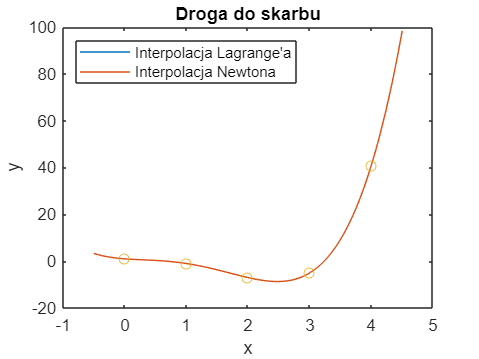

clear all;

x = [0, 4, 1, 2, 3];
y = [1, 41, -1, -7, -5]; 

% Obliczenie wielomianów interpolacyjnych
Lagrange = MojaInterpLagrange(x,y);
Newton = MojaInterpNewtona(x,y);

% Przygotowanie danych do wykresu
a = min(x)-0.5; 
b = max(x)+0.5; 
dx = 0.01; % krok próbkowania
x_vals = a:dx:b;
yLagrange = double(subs(Lagrange, x_vals));
yNewton = double(subs(Newton, x_vals));

% Wykres
figure;
plot(x_vals, yLagrange,x_vals,yNewton,x,y,'o');
legend("Interpolacja Lagrange'a", 'Interpolacja Newtona', Location='northwest');
xlabel('x');
ylabel('y');
title('Droga do skarbu');

Droga przybliżana wielomianami Lagrange'a i Newtona nakładają się na siebie

2.7. Dystans potrzebny do zatrzymania samochodu jest funkcją jego prędkości. Następujące dane eksperymentalne zostały zebrane celem zbadania tej zależności:

 v [km/h] 15 20 25 30 40 50 60

  s [m] 2 2.5 4.25 5 7.5 11.25 15

Ocenić odległość hamowania dla samochodu jadącego z prędkością 45 km/h. Zastosować model liniowy i kwadratowy. Naszkicować odpowiednie wykresy

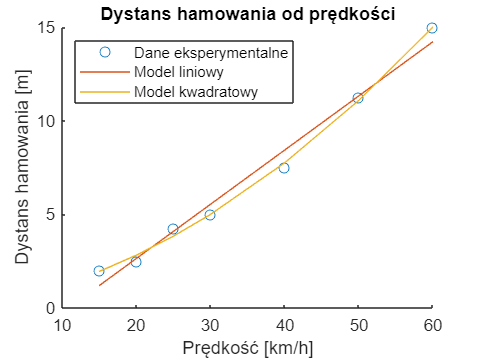

v = [15, 20, 25, 30, 40, 50, 60];
s = [2, 2.5, 4.25, 5, 7.5, 11.25, 15];
%prędkość testowa
vTest=45;
% Model liniowy
% Dopasowanie prostej regresji liniowej
aproksL = polyfit(v, s, 1); 
% Wyliczenie odległości dla prędkości testowej
liniowy = polyval(aproksL, vTest); 

% Model kwadratowy
% Dopasowanie krzywej regresji kwadratowej
aproksK = polyfit(v, s, 2); 
% Wyliczenie odległości dla prędkości testowej
kwadratowy = polyval(aproksK, vTest); 

%Wykres
figure;
% Wykres danych eksperymentalnych
scatter(v, s, 'o'); 
hold on;
plot(v, polyval(aproksL, v)); % Prosta regresji liniowej
plot(v, polyval(aproksK, v)); % Krzywa regresji kwadratowej
xlabel('Prędkość [km/h]');
ylabel('Dystans hamowania [m]');
legend('Dane eksperymentalne', 'Model liniowy', 'Model kwadratowy',Location='northwest');
title('Dystans hamowania od prędkości');


disp(['Model liniowy dla 45 km/h: ', num2str(liniowy), ' m']);

Model liniowy dla 45 km/h: 9.8926 m


disp(['Model kwadratowy dla 45 km/h: ', num2str(kwadratowy), ' m']);

Model kwadratowy dla 45 km/h: 9.3594 m


2.8. Dokonać aproksymacji średniokwadratowej funkcji:

f (x) = x/(x^`2` + 2)

wielomianem 2-go stopnia w przedziale [−1, 1] z krokiem 0.01. Narysować wykres danej funkcji i funkcji przybliżającej w jednym układzie współrzędnych natomiast wykres błędu aproksymacji w drugim. Wyznaczyć maksymalną wartość bezwzględnego błędu aproksymacji w rozpatrywanym przedziale.

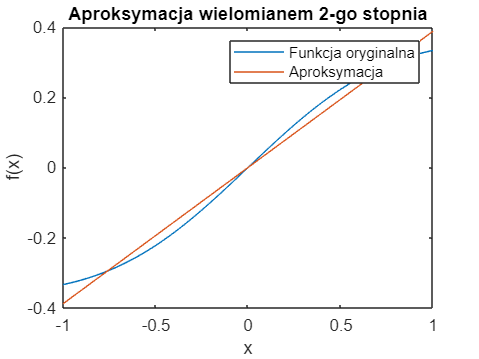

f = @(x) x ./ (x.^2 + 2);
x=-1:0.01:1;
y= f(x);

% Dopasowanie wielomianu 2. stopnia
p = polyfit(x, y, 2);
aproks = polyval(p, x);

% Wyliczenie błędu aproksymacji
error = abs(y - aproks);
maxError = max(error);

% Wykresy
figure;
plot(x, y);
hold on;
plot(x, aproks);
xlabel('x');
ylabel('f(x)');
legend('Funkcja oryginalna', 'Aproksymacja');
title('Aproksymacja wielomianem 2-go stopnia');

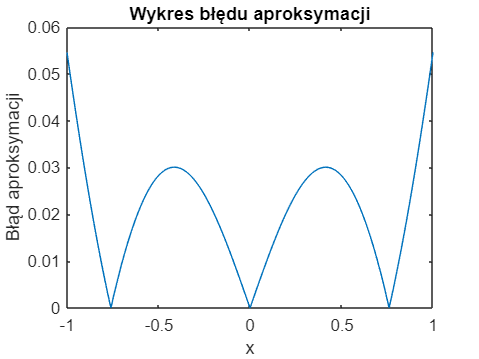


% Wykres błędu
figure;
plot(x, error);
xlabel('x');
ylabel('Błąd aproksymacji');
title('Wykres błędu aproksymacji');


% Wyświetlenie maksymalnej wartości błędu aproksymacji
disp("Maksymalny błąd aproksymacji: " + num2str(maxError));

Maksymalny błąd aproksymacji: 0.05458


2.9. Dopasować model eksponencjalny y(x) = a0*e^(a`1*`x) do danych:

xi 0.4 0.8 1.2 1.6 2.0 2.3

yi 750 1000 1400 2000 2700 3750

Następnie rozwiązać zadanie przez sprowadzenie do problemu regresji liniowej. Porównać rezultaty.

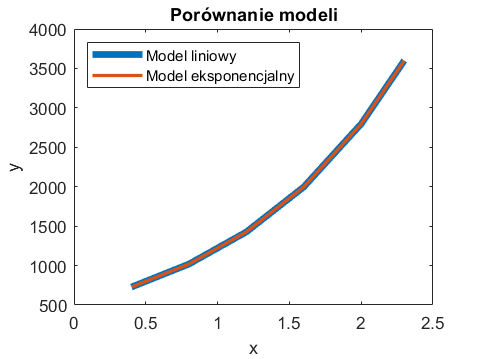

xi = [0.4 0.8 1.2 1.6 2.0 2.3];
yi = [750 1000 1400 2000 2700 3750];

% Model eksponencjalny
eksp = polyfit(xi, log(yi), 1);
%współczynnik przy wyrazie wolnym
a0 = exp(eksp(2));
%współczynnik przy nachyleniu
a1 = eksp(1);
yEksp = a0 * exp(a1 * xi);

% Model liniowy
liniowy = log(yi);
wspolczynniki = polyfit(xi, liniowy, 1);
yLiniowy = exp(polyval(wspolczynniki, xi));

% Wykresy
plot(xi, yLiniowy,'LineWidth', 4);
hold on;
plot(xi, yEksp, 'LineWidth', 2);
xlabel('x');
ylabel('y');
legend('Model liniowy', 'Model eksponencjalny', Location='northwest');
title('Porównanie modeli');

Wykresy się pokrywają

2.10 Wyznaczyć współczynniki wielomianu aproksymującego 2, 3 i 5 stopnia

dla następujących danych:

xi -4.001671 -1.125367 1.342565 2.848678 4.147236 5.971023

yi 1.231469 -3.237849 7.910278 -2.923678 6.347865 8.346236

Napisać własny skrypt i porównać błędy aproksymacji. Sporządzić odpowiednie wykresy

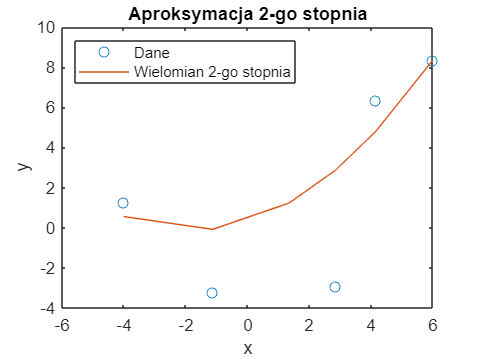

xi = [-4.001671, -1.125367, 1.342565, 2.848678, 4.147236, 5.971023];
yi = [1.231469, -3.237849, 7.910278, -2.923678, 6.347865, 8.346236];

% Wielomian 2 stopnia
x2 = polyfit(xi, yi, 2);
y2 = polyval(x2, xi);
error2 = abs(yi - y2);
maxError2 = max(error2);

% Wielomian aproksymujący stopnia 3
x3 = polyfit(xi, yi, 3);
y3 = polyval(x3, xi);
error3 = abs(yi - y3);
maxError3 = max(error3);

% Wielomian aproksymujący stopnia 5
x5 = polyfit(xi, yi, 5);
y5 = polyval(x5, xi);
error5 = abs(yi - y5);
maxError5 = max(error5);

% Wykresy
figure;
plot(xi, yi, 'o');
hold on;
plot(xi, y2);
xlabel('x');
ylabel('y');
legend('Dane', 'Wielomian 2-go stopnia',Location='northwest');
title('Aproksymacja 2-go stopnia');

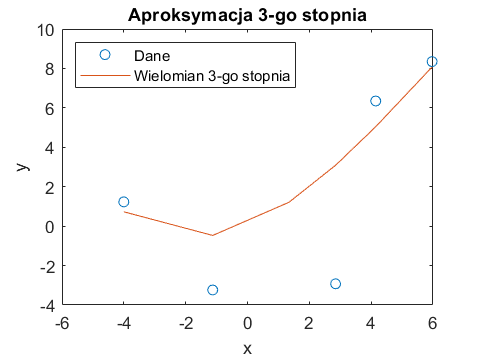


figure
plot(xi, yi, 'o');
hold on;
plot(xi, y3);
xlabel('x');
ylabel('y');
legend('Dane', 'Wielomian 3-go stopnia',Location='northwest');
title('Aproksymacja 3-go stopnia');

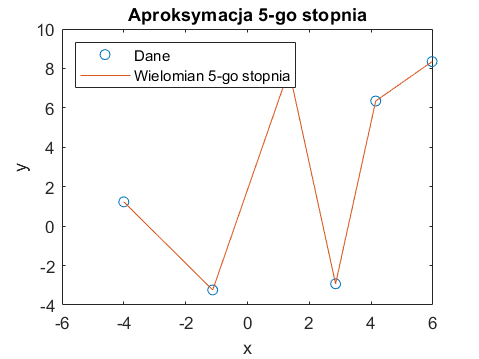


figure
plot(xi, yi,'o');
hold on;
plot(xi, y5);
xlabel('x');
ylabel('y');
legend('Dane', 'Wielomian 5-go stopnia', Location='northwest');
title('Aproksymacja 5-go stopnia');

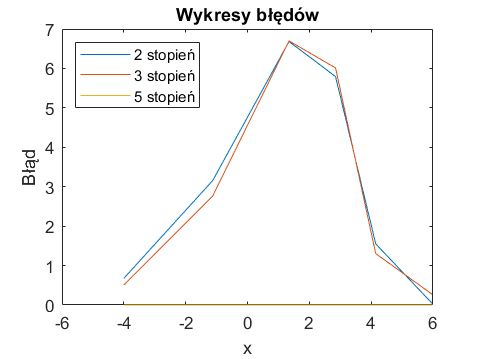


figure
plot(xi, error2);
hold on;
plot(xi, error3);
plot(xi, error5);
xlabel('x');
ylabel('Błąd');
legend('2 stopień', '3 stopień', '5 stopień', Location='northwest');
title('Wykresy błędów');


% Wyświetlenie maksymalnych wartości błędów aproksymacji
disp('Maksymalne wartości błędów aproksymacji:');

Maksymalne wartości błędów aproksymacji:


disp(['2-go stopnia: ', num2str(maxError2)]);

2-go stopnia: 6.6822


disp(['3-go stopnia: ', num2str(maxError3)]);

3-go stopnia: 6.6982


disp(['5-go stopnia: ', num2str(maxError5)]);

5-go stopnia: 1.9362e-13


Tylko aproksymacja 5 stopnia dała dobre wyniki i miała niewielki błąd